# Building and Solving a Mathematical Programming / Optimization Model

This an example of how to use MP-Opt-Model to build and solve an optimization model, in this case, a mixed-integer, linear programming (MILP) problem.

## Multi-Plant Production and Distribution Example Problem

A company operates **two production plants** and needs to satisfy **customer demand** for two products, ***Y*** and ***Z***.

- **Plants** can be opened or closed.

- Each plant incurs a **fixed cost** if it is used.

- Each plant has a **capacity limit** (maximum total units it can ship).

- Products must be shipped from plants to customers.

- Products are produced as needed for shipping, with no extra inventory.

- Delivery costs depend on the plant, customer, and product and include production and shipping.

- All customer demand must be fully satisfied (no shortages allowed).

- Shipping from a plant is only allowed if that plant is open.

**Goals**

The goal is to decide:

- Which plants to open.

- How much of each product to ship from each open plant to each customer.

To **minimize total cost**:

- Sum of **plant fixed costs** (if used)

- Plus **delivery costs** for all products shipped

## Problem Data

We begin by defining the data for our problem.

### Plants

$m_{p}$ : capacity of plant $p$

**Each plant has capacity to serve the entire demand alone if needed.**

PlantCapacity = [ 60; 60 ]      % Plants 1, 2

PlantCapacity =     60
    60


### **Products & Demand**

- **Products**: 2 products

- **Customers**: 3 customers

- **Demand** (units to be delivered to each customer):

#### **Customer Demand**

$d_y$  : $3\times 1$ vector of demand for product ***Y*** for Customers 1, 2, 3

$d_z$  : $3\times 1$ vector of demand for product ***Z*** for Customers 1, 2, 3

CustomerDemandY = [ 10; 15; 5 ]     % Customers 1, 2, 3

CustomerDemandY =     10
    15
     5


CustomerDemandZ = [  8; 12; 6 ]     % Customers 1, 2, 3

CustomerDemandZ =      8
    12
     6


#### **Product *****Y***** Delivery Cost*** (per unit shipped)*

$c_{y_p }$ : $3\times 1$ vector of delivery cost of product ***Y*** from plant $p$ to Customers 1, 2, 3

#### **Product *****Z***** Delivery Cost*** (per unit shipped)*

$c_{z_p }$ : $3\times 1$ vector of delivery cost of product ***Z*** from plant $p$ to Customers 1, 2, 3

DeliveryCostY = [
%   Plant 1     Plant 2
    4           7;          % Customer 1
    5           6;          % Customer 2
    3           8           % Customer 3
]

DeliveryCostY =      4     7
     5     6
     3     8


DeliveryCostZ = [
%   Plant 1     Plant 2
    10          4;          % Customer 1
     9          5;          % Customer 2
    12          3           % Customer 3
]

DeliveryCostZ =     10     4
     9     5
    12     3


#### Plant Fixed Costs

$c_{u,s}$ : $2\times 1$ vector of plant fixed costs, for plants 1, 2 in scenario $s$

PlantFixedCost = [
%   Scenario 1  Scenario 2  Scenario 3
    100         100          50;    % Plant 1
    200         100         120     % Plant 2
]

PlantFixedCost =    100   100    50
   200   100   120


## Problem Formulation

For scenarios $s=1,2,3$, our problem takes the form of a mixed-integer linear program (MILP), which has the following form.

        
$$\min_x \;c_s^{\top } x$$


    such that

        
$$l\le A\;x\le u$$


        
$$x_\textrm{min} \le x \le x_\textrm{min}$$


        
$$x_j \textrm{ binary, for}\; j \in \cal{J}$$


Below, $0$, $1$, and $\infty$ are used to refer to the normal scalar values, as well as the corresponding vectors or matrices of appropriate dimensions.

We begin by creating the model object. We will begin with **scenario 1**, then modify the fixed costs of the plants for scenarios 2 and 3.

Scenario = 1    % build scenario 1 initially

Scenario = 1


% create the model object
mm = mp.opt_model();

### Decision variables

The next step is to add the decision variables for the problem, specifying a name and dimension, along with an initial value *(which we leave empty)*, and any lower or upper bounds. Variable sets are managed by `mm.var`.

#### *Plant Status*

$u$ : $2\times 1$ binary vector, status of plants 1, 2

        $0\le u\le 1$, with no initial value provided

% add set of binary variable of dimension 2, named 'u'
mm.var.add('u', 2, [], 0, 1, 'B');

#### *Product Delivery*

In this case, we have a vector of each product for each plant, so we name the variable sets by product, with a single index for the plant. Each is a vector corresponding to 3 customers. Because these variable sets are identified by a name **and** an index, we need to initialize the set name with the dimensions of the indexing.

$y_p$ : $3\times 1$ vector, number of units of product ***Y*** shipped from plant $p$ to customers 1, 2, 3

$z_p$ : $3\times 1$ vector, number of units of product ***Z*** shipped from plant $p$ to customers 1, 2, 3

        $0\le y_p$, with no upper bound and no initial value provided

        $0\le z_p$, with no upper bound and no initial value provided


% prepare to add 2 sets of 'y' and 'z' variables, indexed by plant
mm.var.init_indexed_name('y', {2});
mm.var.init_indexed_name('z', {2});

% add them, each with dimension 3, one for each customer
% bounded below by 0, no upper bound
for p = 1:2
    mm.var.add('y', {p}, 3, [], 0);     % Product Y, Plant p to Customers 1-3
    mm.var.add('z', {p}, 3, [], 0);     % Product Z, Plant p to Customers 1-3
end

% display model variables
% show starting/ending indices, dimensions for each set
mm.var

VARIABLES                    name       i1       iN        N
=========                  ------    -----    -----   ------
         1:                     u        1        2        2
         2:                  y{1}        3        5        3
         3:                  z{1}        6        8        3
         4:                  y{2}        9       11        3
         5:                  z{2}       12       14        3
         5 = ans.NS                              14 = ans.N



### Costs

Next we add the costs that are used in the objective function. Linear and quadratic cost sets are managed by `mm.qdc`, and since all of our costs are linear, the quadratic and constant term coefficients are empty.

Each cost term depends on a single variable set, so we specify the variable set explicitly for each cost set added. For $u$, the variable set argument is a cell array with the name only. For $y_p$ and $z_p$, it is a struct with both name and index. In the latter case, the cost sets are also indexed, just like the corresponding variable sets, so the names must be initialized with the dimension.

#### *Plant Fixed Costs*

% add fixed costs, providing coefficients for 'u' variables only
mm.qdc.add(mm.var, 'fixed', [], PlantFixedCost(:, Scenario), [], {'u'});

#### *Delivery Costs*

% prepare to add 2 sets of delivery costs per product, indexed by plant
mm.qdc.init_indexed_name('delivery_y', {2});
mm.qdc.init_indexed_name('delivery_z', {2});

% add costs for plant p, for each product, corresponding to variable sets
% 'y{p}' and 'z{p}'; each is 3 x 1 corresponding to the 3 customers
for p = 1:2
    vs_y = struct('name', 'y', 'idx', {{p}});    % variable set for 'y{p}'
    vs_z = struct('name', 'z', 'idx', {{p}});    % variable set for 'z{p}'
    mm.qdc.add(mm.var, 'delivery_y', {p}, [], DeliveryCostY(:, p), [], vs_y);
    mm.qdc.add(mm.var, 'delivery_z', {p}, [], DeliveryCostZ(:, p), [], vs_z);
end

% display model costs
% show starting/ending indices, dimensions for each set
mm.qdc

QUADRATIC COSTS              name       i1       iN        N
===============            ------    -----    -----   ------
         1:                 fixed        1        2        2
         2:         delivery_y{1}        3        5        3
         3:         delivery_z{1}        6        8        3
         4:         delivery_y{2}        9       11        3
         5:         delivery_z{2}       12       14        3
         5 = ans.NS                              14 = ans.N



### Constraints

Finally, we add the constraints to the model. Our constraints are all linear, so the constraint sets are managed by `mm.lin`.

#### *Plant Capacity Constraints*

Since the constraint set for plant capacity involves all of the variables, we need not specify explicitly the variable sets, only the full constraint matrix and any constraint bounds.

    
$$\left\lbrack \begin{array}{ccccc}
m_1  & 1 & 1 & 0 & 0\\
m_2  & 0 & 0 & 1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
y_1 \\
z_1 \\
y_2 \\
z_2 
\end{array}\right\rbrack \le \left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$


% define based on full set of variables: u y{1} y{2} z{1} z{2}
Au = -spdiags(PlantCapacity, 0, 2, 2);
Ayz = sparse([1 1 1 1 1 1 0 0 0 0 0 0;   % sum for plant 1
              0 0 0 0 0 0 1 1 1 1 1 1]); % sum for plant 2
ub = 0;    % constraint upper bound (no lower bound)
mm.lin.add(mm.var, 'capacity', [Au Ayz], [], ub);

#### *Demand Satisfaction Constraints*

Since each set of demand satisfaction constraints depends only on the delivery variables for the corresponding product, we specify the corresponding variable sets explicitly, eliminating the need to place appropriately sized zero blocks for the rest of the variables. Since these are equality constraints, the lower and upper bounds on the constraints have the same value.

        
$$\left\lbrack \begin{array}{cc}
I & I
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =d_y$$


        
$$\left\lbrack \begin{array}{cc}
I & I
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
z_1 \\
z_2 
\end{array}\right\rbrack =d_z$$


% demand for product Y: based on variable sets: y{1} y{2} only
vs_y = struct('name', 'y', 'idx', {{1}, {2}});
Ad = [speye(3) speye(3)];
mm.lin.add(mm.var, 'demand_y', Ad, CustomerDemandY, CustomerDemandY, vs_y);

% demand for product Z: based on variable sets: z{1} z{2} only
vs_z = struct('name', 'z', 'idx', {{1}, {2}});
mm.lin.add(mm.var, 'demand_z', Ad, CustomerDemandZ, CustomerDemandZ, vs_z);

% display model constraints
% show starting/ending indices, dimensions for each set
mm.lin

LINEAR CONSTRAINTS           name       i1       iN        N
==================         ------    -----    -----   ------
         1:              capacity        1        2        2
         2:              demand_y        3        5        3
         3:              demand_z        6        8        3
         3 = ans.NS                               8 = ans.N



## Solve the Model

Solving the model involves simply calling the `solve()` method on the model object. Various options can be provided through an options struct to control output, select the solver, and specify solver options.

opt = struct('verbose', 2, 'skip_prices', true);
mm.solve(opt);

Gurobi Version 12.0.2 -- automatic MILP solver
Set parameter LicenseID to value 2404174
Set parameter DisplayInterval to value 100
Gurobi Optimizer version 12.0.2 build v12.0.2rc0 (mac64[arm] - Darwin 24.5.0 24F74)

CPU model: Apple M2 Max
Thread count: 12 physical cores, 12 logical processors, using up to 12 threads

Non-default parameters:
DisplayInterval  100
LogToConsole  0

Optimize a model with 8 rows, 14 columns and 26 nonzeros
Model fingerprint: 0x32709368
Variable types: 12 continuous, 2 integer (2 binary)
Coefficient statistics:
  Matrix range     [1e+00, 6e+01]
  Objective range  [3e+00, 2e+02]
  Bounds range     [1e+00, 1e+00]
  RHS range        [5e+00, 2e+01]
Presolve removed 8 rows and 14 columns
Presolve time: 0.00s
Presolve: All rows and columns removed

Explored 0 nodes (0 simplex iterations) in 0.05 seconds (0.00 work units)
Thread count was 1 (of 12 available processors)

Solution count 1: 490 

Optimal solution found (tolerance 1.00e-04)
Best objective 4.90000000000

#### Display the Full Solution

mm.display_soln();

=====  VARIABLES  =====
  idx    description                   mu_lb     lb       val      ub      mu_ub
------- ---------------------------- -------- -------- -------- -------- --------
   1    u(1)                                         0        1        1         
   2    u(2)                                         0        0        1         
   3    y{1}(1)                                      0       10       -          
   4    y{1}(2)                                      0       15       -          
   5    y{1}(3)                                      0        5       -          
   6    z{1}(1)                                      0        8       -          
   7    z{1}(2)                                      0       12       -          
   8    z{1}(3)                                      0        6       -          
   9    y{2}(1)                                      0        0       -          
  10    y{2}(2)                                      0        0       -    

## Three Scenarios

Now we loop through the 3 scenarios, modifying the fixed cost of the plants for the scenario and re-solving the optimization problem.

The amount of each product from each plant is then shown in a column chart.

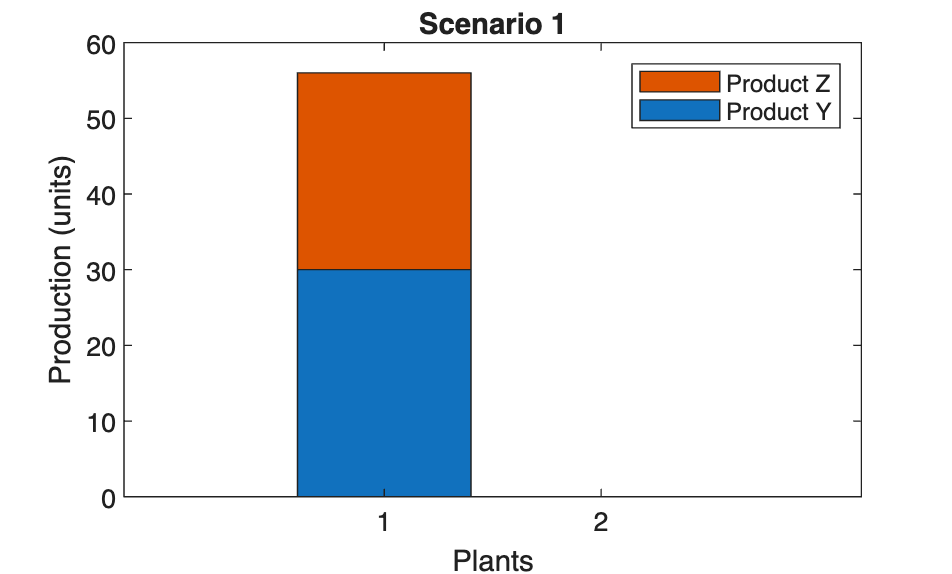

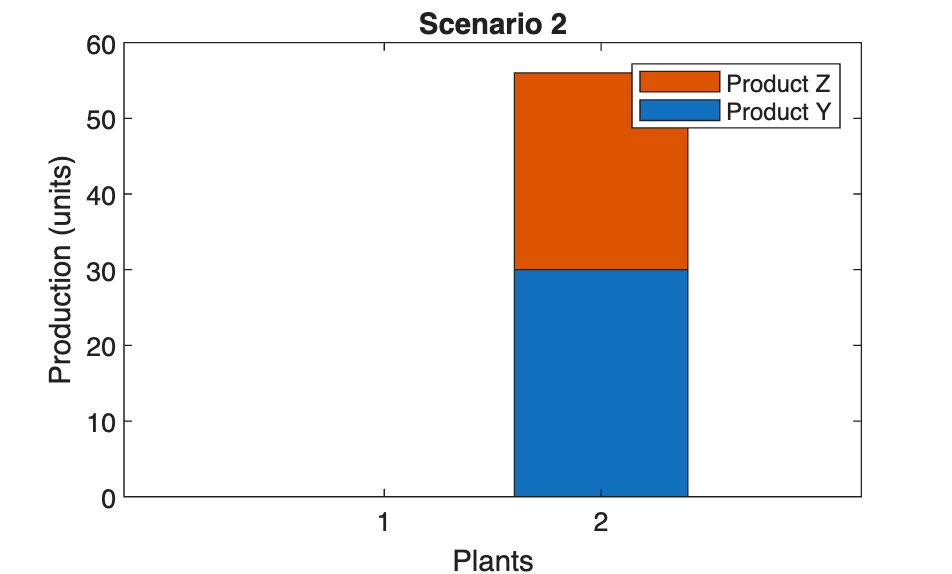

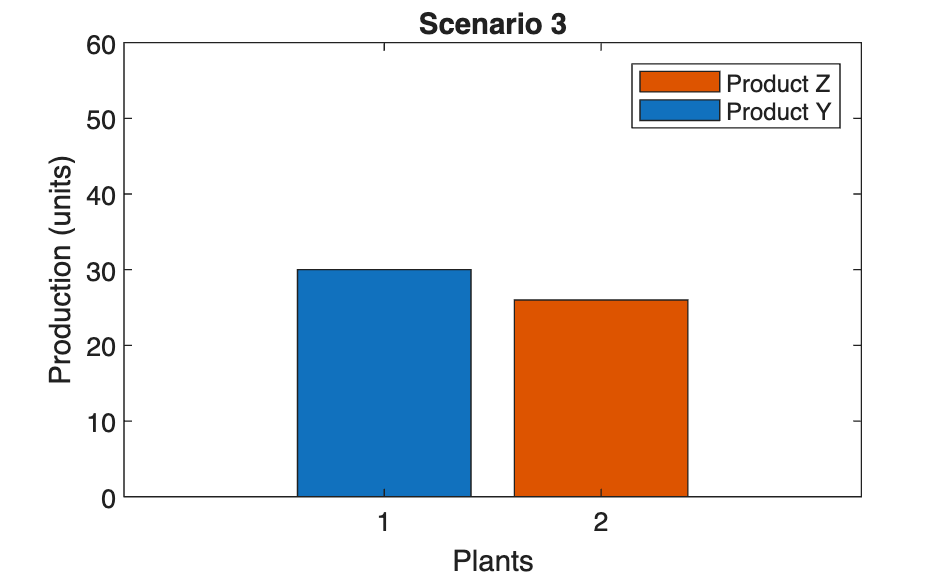

for Scenario = 1:3
    mm.qdc.set_params(mm.var, 'fixed', 'c', PlantFixedCost(:, Scenario));
    mm.solve();

    y1 = sum(mm.var.get_soln(mm.soln, 'y', {1}));   % product Y from plant 1
    y2 = sum(mm.var.get_soln(mm.soln, 'y', {2}));   % product Y from plant 2
    z1 = sum(mm.var.get_soln(mm.soln, 'z', {1}));   % product Z from plant 1
    z2 = sum(mm.var.get_soln(mm.soln, 'z', {2}));   % product Z from plant 2

    figure;
    bar([y1 z1; y2 z2], 'stacked');
    ax = axis();
    axis([ax(1:3) 60]);
    title(sprintf('Scenario %d', Scenario));
    legend({'Product Y', 'Product Z'});
    xlabel('Plants');
    ylabel('Production (units)');
end